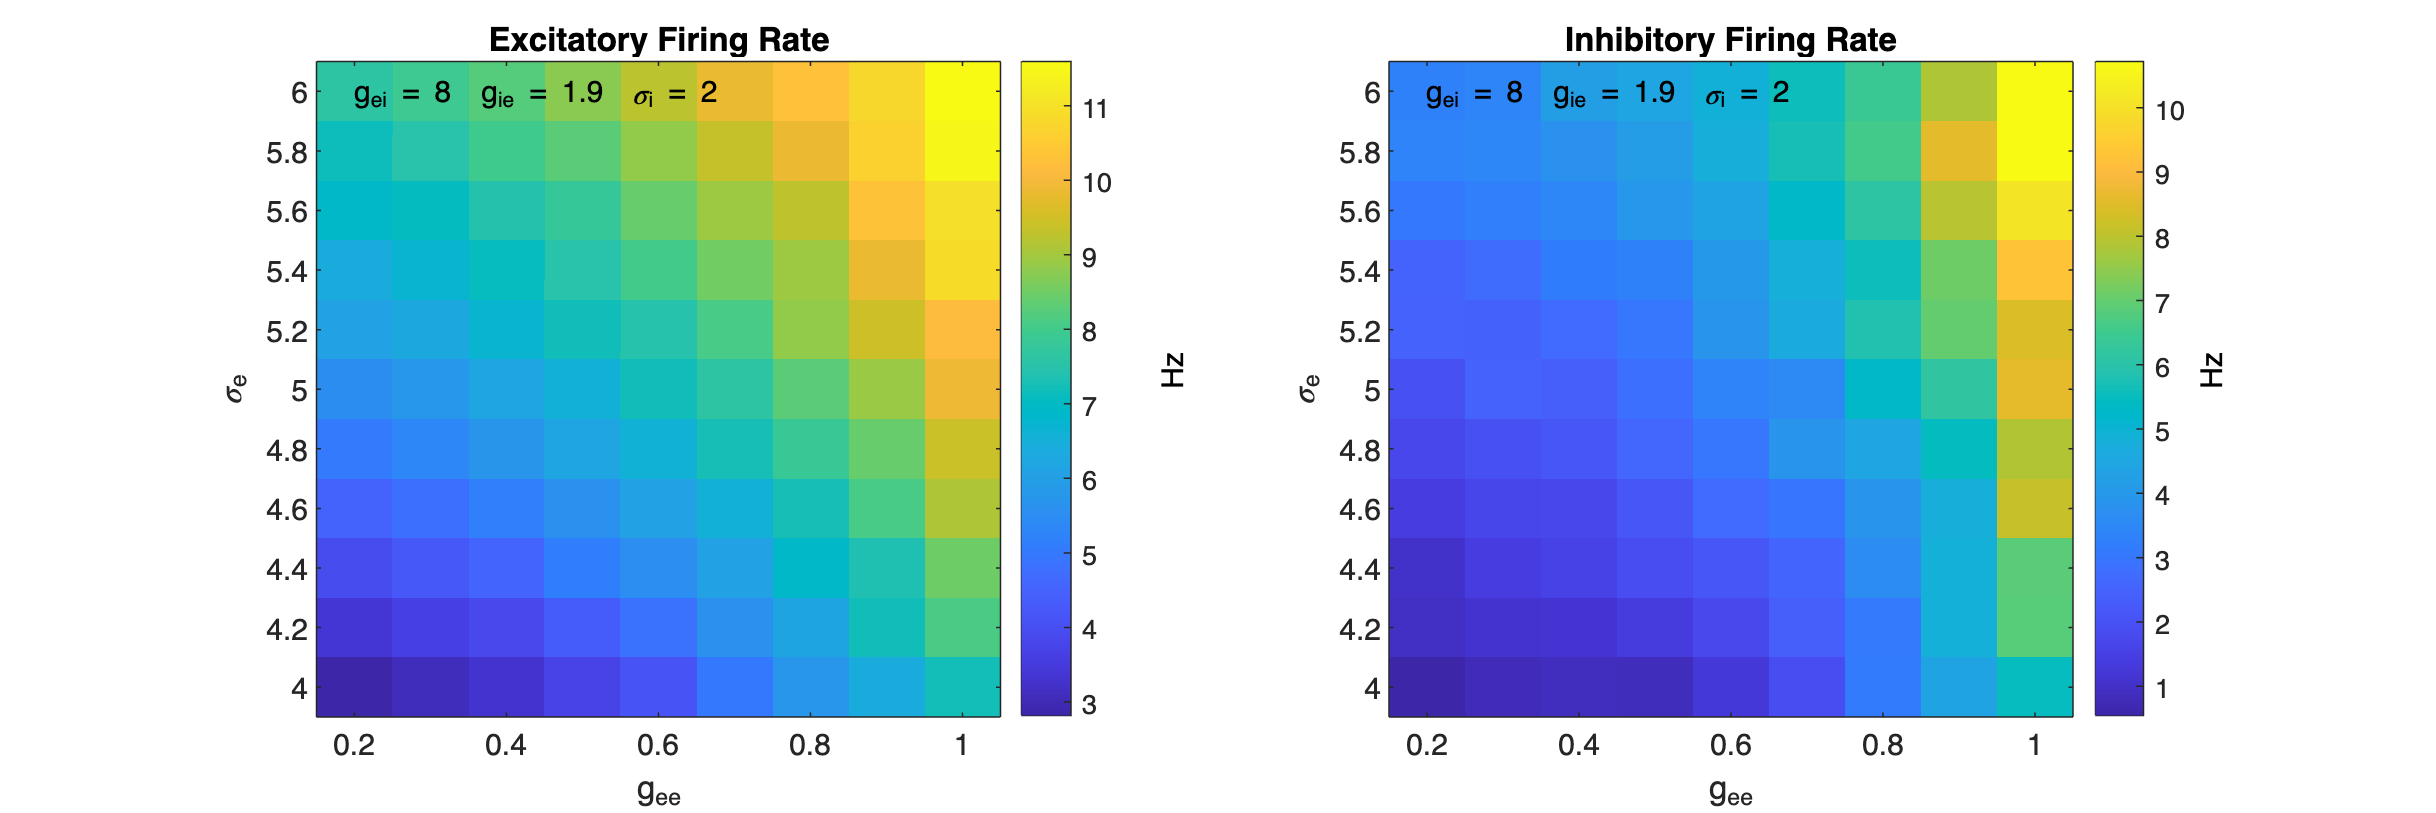

clear 
clc
load("NetwerkLevel/JustNoise/PhaseSpace1.mat")
f1 = 1; f2 = 4;


fields_name = {'g_{ee}', 'g_{ei}', 'g_{ie}', '\sigma_{e}', '\sigma_{i}'};
fields = {G_ee_range, G_ei_range, G_ie_range, SigmaEx_range, SigmaInh_range};

command = "";
caption = "";
for i = 1:5
    if i == f1 || i == f2
        command = strcat(command, " :");
    else
        command = strcat(command, strcat(" " , int2str(round(length(fields{i})/2))));
        caption = strcat(caption, fields_name{i}, " = ", num2str(fields{i}(round(length(fields{i})/2))) , "  ");
    end
end

command = strtrim(command);
command = strrep(command, ' ', ',');
FR_Ex = squeeze( eval(strcat('firing_rates_ex','(', command, ')')) );
FR_Inh = squeeze( eval(strcat('firing_rates_inh','(', command, ')')) );

max_firing_rate = max([max(FR_Ex(:)), max(FR_Inh(:))]);
min_firing_rate = min([min(FR_Ex(:)), min(FR_Inh(:))]);


fig = figure('Position', [0, 0, 1200, 400]);

subplot(1, 2, 1)
%imagesc(fields{f1}, fields{f2}, FR_Ex, [min_firing_rate, max_firing_rate])
imagesc(fields{f1}, fields{f2}, transpose(FR_Ex))
xlabel(fields_name{f1})
ylabel(fields_name{f2})
title('Excitatory Firing Rate')
colorbar()
set(gca,'YDir','normal')
text(0.05, 0.95, caption, 'Units', 'normalized')
text(1.25, 0.5, "Hz", 'Units', 'normalized', 'Rotation',90);

subplot(1, 2, 2)
%imagesc(fields{f1}, fields{f2}, FR_Inh, [min_firing_rate, max_firing_rate])
imagesc(fields{f1}, fields{f2}, transpose(FR_Inh))
xlabel(fields_name{f1})
ylabel(fields_name{f2})
title('Inhibitory Firing Rate')
colorbar()
set(gca,'YDir','normal')
text(0.05, 0.95, caption, 'Units', 'normalized');
text(1.2, 0.5, "Hz", 'Units', 'normalized', 'Rotation',90);